% This part is trying to overlay the gradient contrast image with the
% intensity map to see whether there's any patter for autofluorescence
% expression
% the summarized overlayyed images are in powerpoint /Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/autofluorescence.pptx
% It looks like some aggregates-like fluorescence is closer to membrane
baseName = '20221224autofluoHEK001';
cd('/Users/pingchuanma/Desktop/ChenLab_Data/Fixed_ACh_data/20221224autofluoHEK001')

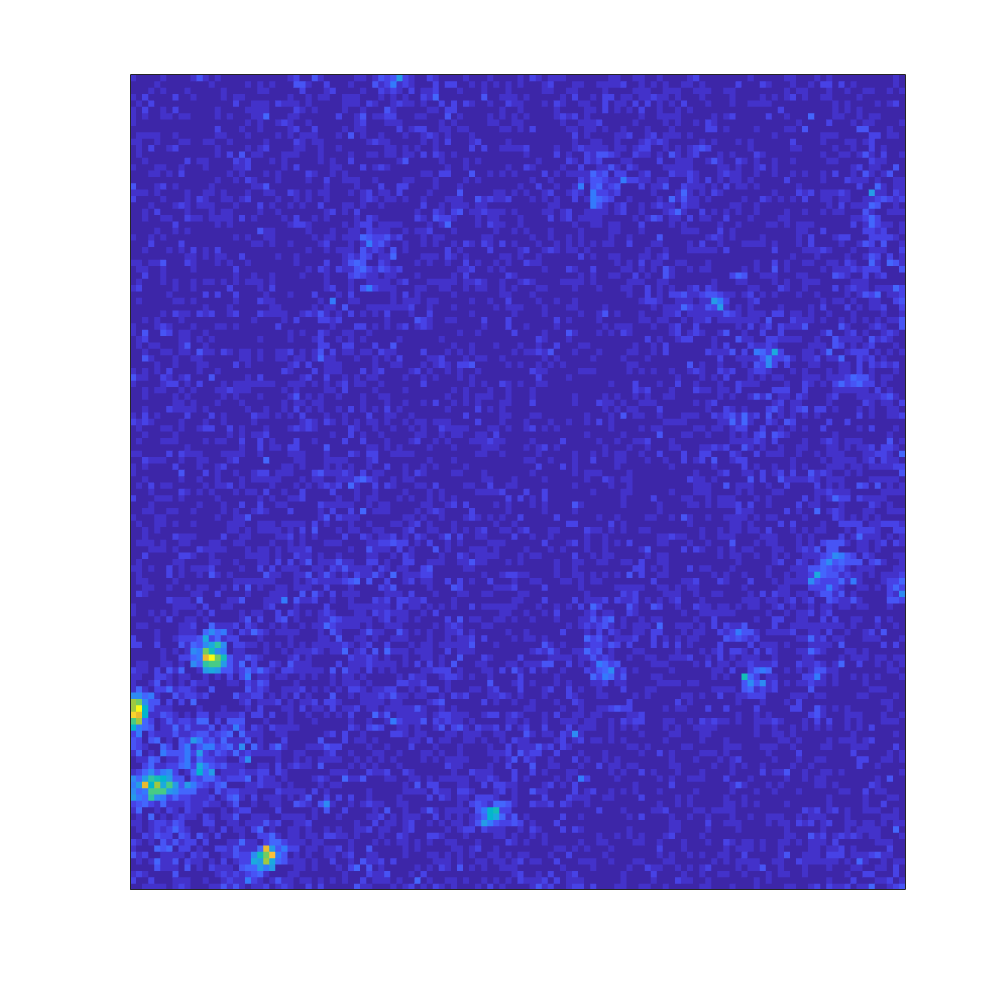


% Read the tif image channel2

for i = 1
    tiff_name = [baseName, '00', num2str(i), '.tif'];
    spc_name = [baseName, 'FLIM00', num2str(i), '.mat'];
    spc_data = load(spc_name);
    intensity_name = [num2str(i), '_intensity.tiff'];
    GC_image_name = [num2str(i), '_GC.png'];
    intensity_image = spc_data.spcSave.projects{1};
    f1 = figure('Position', [10 10 500 500]);
    h = heatmap(intensity_image);
    h.Colormap = parula;
    Ax=gca;
    Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
    Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
    h.ColorbarVisible='off';
    h.GridVisible='off';
    saveas(f1, intensity_name);


    GC_image = imread(tiff_name, 2);
    GC_image = double(GC_image);
    GC_image(GC_image < 500) = 500;
    GC_image(GC_image > 2000) = 2000;

    f2 = figure('visible','off','Position', [10 10 500 500]);
    h = heatmap(GC_image);
    h.Colormap = gray;
    Ax=gca;
    Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
    Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
    h.ColorbarVisible='off';
    h.GridVisible='off';
    saveas(f2, GC_image_name)
end


for i = 10:15
    tiff_name = [baseName, '0', num2str(i), '.tif'];
    spc_name = [baseName, 'FLIM0', num2str(i), '.mat'];
    spc_data = load(spc_name);
    intensity_name = [num2str(i), '_intensity.png'];
    GC_image_name = [num2str(i), '_GC.png'];
    
    intensity_image = spc_data.spcSave.projects{1};
    f1 = figure('visible','off','Position', [10 10 500 500]);
    h = heatmap(intensity_image);
    h.Colormap = parula;
    Ax=gca;
    Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
    Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
    h.ColorbarVisible='off';
    h.GridVisible='off';
    saveas(f1, intensity_name);


    GC_image = imread(tiff_name, 2);
    GC_image = double(GC_image);
    GC_image(GC_image < 500) = 500;
    GC_image(GC_image > 2000) = 2000;

    f2 = figure('visible','off','Position', [10 10 500 500]);
    h = heatmap(GC_image);
    h.Colormap = gray;
    Ax=gca;
    Ax.XDisplayLabels = nan(size(Ax.XDisplayData));
    Ax.YDisplayLabels = nan(size(Ax.YDisplayData));
    h.ColorbarVisible='off';
    h.GridVisible='off';
    saveas(f2, GC_image_name)
end

createdMasks = {};
intensity_map_all = {};

spc_lifetimes_AF_all = {};

i_img = 1;

% draw roi and run this
createdMasks{i_img} = gui.gy.rois{1}.mask;

spc_lifetimes_AF = zeros(256,1);
mask = gui.gy.rois{1}.mask;
for i_x = 1:128
    for i_y = 1:128
        if mask(i_x,i_y)==1
            spc_lifetimes_AF = spc_lifetimes_AF + spc.imageMods{1}(:,i_x, i_y);
        end
    end
end

spc_lifetimes_AF_all{i_img} = spc_lifetimes_AF;

i_img = i_img + 1;


spc_lifetimes_AF_all = {};
AF_ROIsize = zeros(1,15);

for i = 1:9
    spc_name = [baseName, 'FLIM00', num2str(i), '.mat'];
    spc_data = load(spc_name);
    sum(spc_data.spcSave.lifetimes{1})/(128*128)
    display_mask = createdMasks{i};
    ROI_size = sum(sum(display_mask));
    AF_ROIsize(i) = ROI_size;
    spc_lifetimes_AF = zeros(256,1);
    for i_x = 1:128
        for i_y = 1:128
            if display_mask(i_x,i_y)==1
                spc_lifetimes_AF = spc_lifetimes_AF + spc_data.spcSave.imageMods{1}(:,i_x, i_y);
            end
        end
    end

    sum(spc_lifetimes_AF);

    spc_lifetimes_AF_all{i} = spc_lifetimes_AF;

end

ans = 0.6349

ans = 0.6636

ans = 0.7897

ans = 0.6960

ans = 0.7694

ans = 0.6024

ans = 0.7266

ans = 0.7750

ans = 0.7358


for i = 10:15
    spc_name = [baseName, 'FLIM0', num2str(i), '.mat'];
    spc_data = load(spc_name);
    sum(spc_data.spcSave.lifetimes{1})/(128*128)
    display_mask = createdMasks{i};
    ROI_size = sum(sum(display_mask));
    AF_ROIsize(i) = ROI_size;
    spc_lifetimes_AF = zeros(256,1);
    for i_x = 1:128
        for i_y = 1:128
            if display_mask(i_x,i_y)==1
                spc_lifetimes_AF = spc_lifetimes_AF + spc_data.spcSave.imageMods{1}(:,i_x, i_y);
            end
        end
    end

    sum(spc_lifetimes_AF);

    spc_lifetimes_AF_all{i} = spc_lifetimes_AF;

end

ans = 0.4893

ans = 0.6756

ans = 0.9029

ans = 1.1352

ans = 0.9266

ans = 1.0544

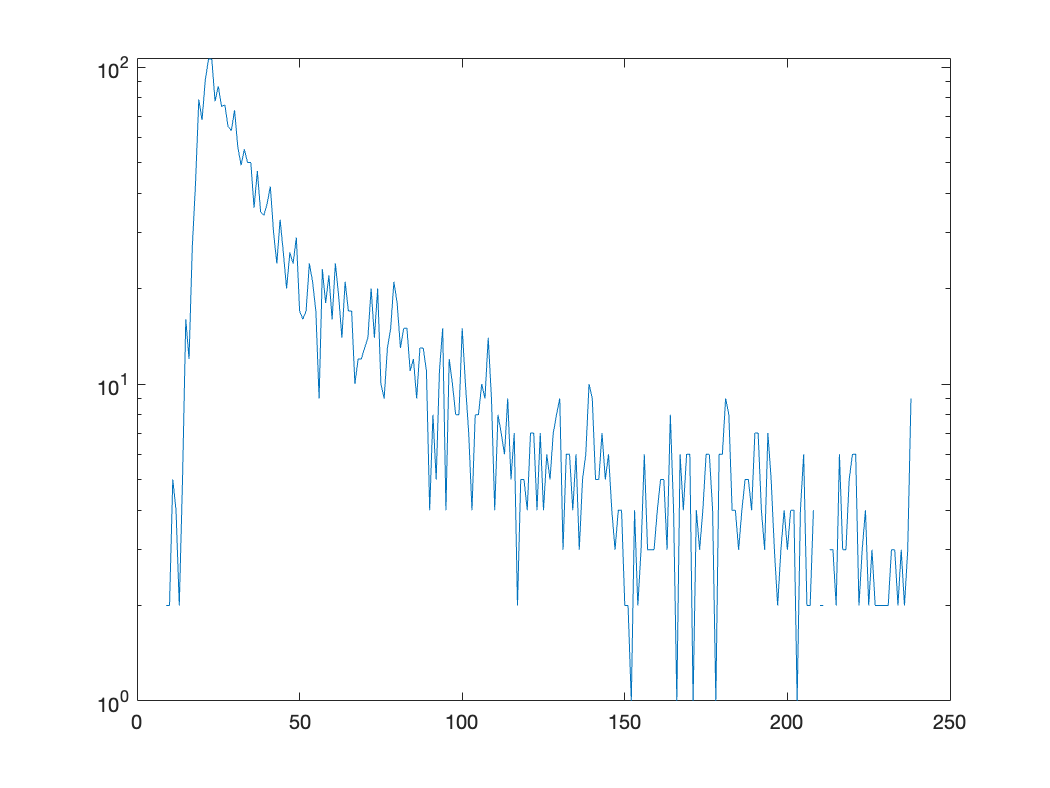

spc_lifetimes_AF_sum = zeros(256,1);

for i = i:15
    this_histogram = spc_lifetimes_AF_all{i};
    spc_lifetimes_AF_sum = spc_lifetimes_AF_sum + this_histogram;
end

figure
semilogy(spc_lifetimes_AF_sum)

sum(spc_lifetimes_AF_sum)/sum(AF_ROIsize)

ans = 0.0623

f3 = imread(f1)

Error using imread>parse_inputs
The file name or URL argument must be a character vector or
string scalar.

Error in imread (line 342)
[source, fmt_s, extraArgs, was_cached_fmt_used] = parse_inputs(cached_fmt, varargin{:});

B = imoverlay(f3, display_mask);
figure('Position', [10 10 500 500])
imagesc(B)
axis off
colormap("parula")
saveas(gcf, 'test.png')

AF_histogram = zeros(1,256);
DarkCount_mean_per_channel = 2711.66666666667/256

DarkCount_mean_per_channel = 10.5924


for i = 1:9
    spc_name = [baseName, 'FLIM00', num2str(i), '.mat'];
    spc_data = load(spc_name);
    sum(spc_data.spcSave.lifetimes{1})
    sum(sum(spc_data.spcSave.projects{1}))
    AF_histogram(9:238) = AF_histogram(9:238) + (spc_data.spcSave.lifetimes{1}(9:238)-DarkCount_mean_per_channel);
end

ans = 10403

ans = 10403

ans = 10872

ans = 10872

ans = 12939

ans = 12939

ans = 11403

ans = 11403

ans = 12606

ans = 12606

ans = 9869

ans = 9869

ans = 11904

ans = 11904

ans = 12698

ans = 12698

ans = 12055

ans = 12055


for i = 10:15
    spc_name = [baseName, 'FLIM0', num2str(i), '.mat'];
    spc_data = load(spc_name);
    sum(spc_data.spcSave.lifetimes{1})
    sum(sum(spc_data.spcSave.projects{1}))
    AF_histogram(9:238) = AF_histogram(9:238) + (spc_data.spcSave.lifetimes{1}(9:238)-DarkCount_mean_per_channel);
end

ans = 8016

ans = 8016

ans = 11069

ans = 11069

ans = 14793

ans = 14793

ans = 18599

ans = 18599

ans = 15181

ans = 15181

ans = 17276

ans = 17276

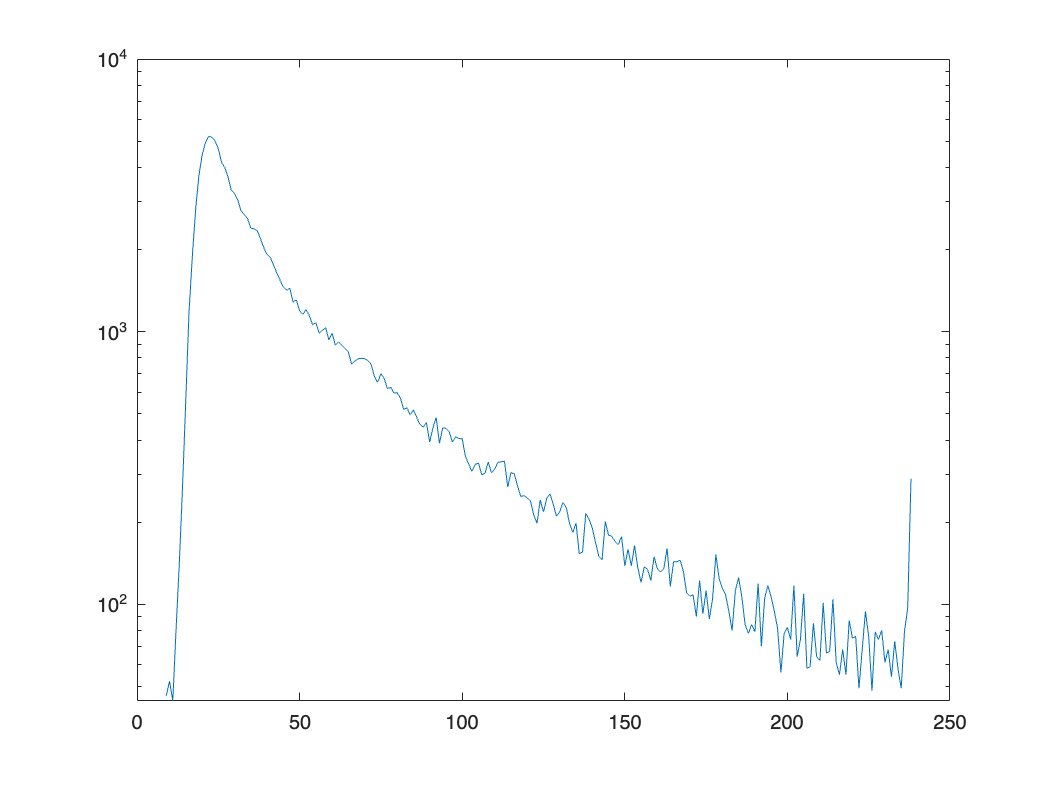


figure
semilogy(AF_histogram)


AF_histogram_norm = AF_histogram/sum(AF_histogram);

AF_pixel = sum(AF_histogram)/(128*128*15)

AF_pixel = 0.6231


save('autofluorescence_20230102.mat', 'AF_histogram_norm', 'AF_pixel')


